## Ordinary Differential Equations

This notebook includes some exercises to calculate solutions to ordinary differential equations both numerically and symbolically in MATLAB. Prepared for EAS Practical Coding and Math course at Georgia Tech.

### Numerical solutions to ODE IVPs

First lets define a weird ODE $\frac{\textrm{dy}}{\textrm{dt}}=y\;\sin \left(t^2 \right)$ which doesn't have an obvious solution. If we want to specify the initial value problem (IVP), we need to specify an "initial condition": $y\left(t=0\right)=1$. Otherwise, any solution would have unknown integration constants.

We start by defining the right hand side of the ODE as an anonymous function

RHS = @(t,y) y*sin(t^2)

RHS = function_handle with value:
    @(t,y)y*sin(t^2)


MATLAB has many ODE solvers built in, which each use different methods to solve initial value problems. If you'd like to learn more about how they do this, take EAS 6130. One very commonly used solver that is good for problems where the solution won't change very quickly and which is accurate for most problems is ode45. The first input is the function handle for the right hand side of the ODE, the second is the span over which the ODE is being solved, and the third is the initial condition

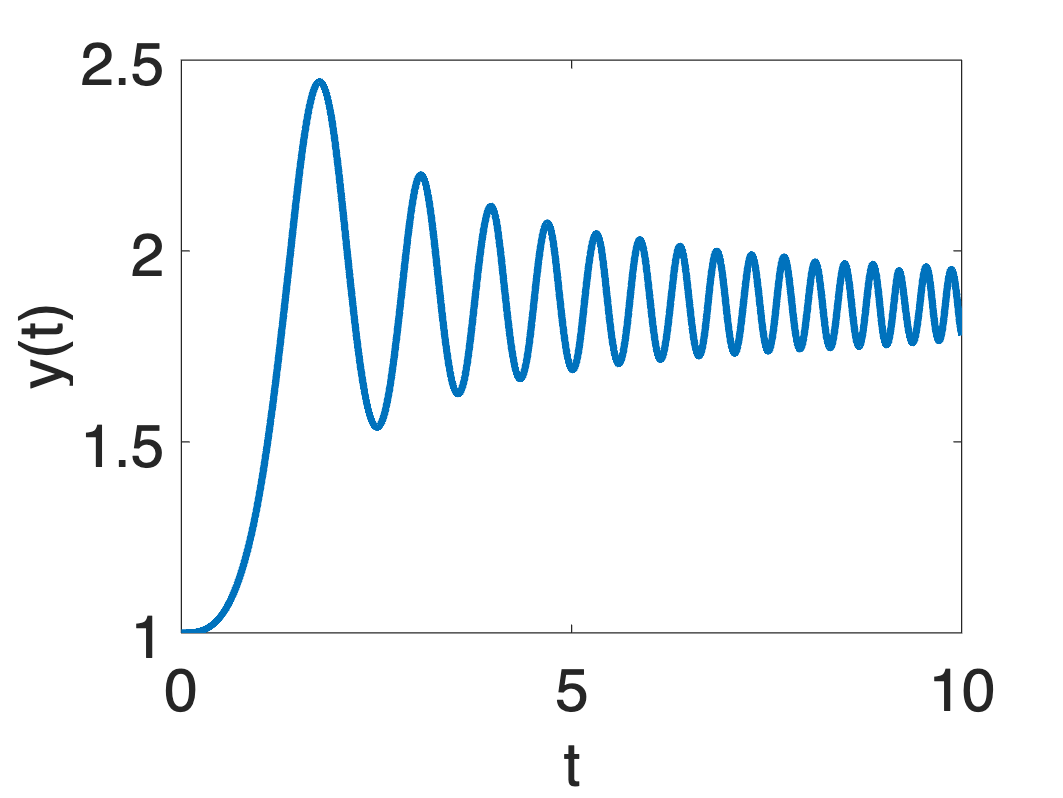

tspan = linspace(0,10,1e4);
[t_out,y_out] = ode45(RHS,tspan,1);
plot(t_out,y_out,'linewidth',3);
set(gca,'fontsize',24)
xlabel('t','fontsize',24)
ylabel('y(t)','fontsize',24)

### Symbolic/Analytic solutions to ODE IVPs

First lets define the function that we want to solve for

syms y(t)

Then we can define the ODE similarly to how we defined the derivative, but using an == sign for equality

ode = diff(y,t) == y*sin(t^2)

$$ode(t) = \frac{\partial }{\partial t}y\left(t\right)=\sin\left(t^{2}\right)\,y\left(t\right)$$

To solve we then just use the dsolve function in MATLAB's symbolic toolbox

ySol(t) = dsolve(ode)

$$ySol(t) = C_{1}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\pi }\,S\left(\frac{\sqrt{2}\,t}{\sqrt{\pi }}\right)}{2}}$$

If we want to formulate this as an IVP, we can add an initial condition to dSolve

ic = y(0) == 1;
ySol(t) = dsolve(ode,ic)

$$ySol(t) = {\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\pi }\,S\left(\frac{\sqrt{2}\,t}{\sqrt{\pi }}\right)}{2}}$$

And then we can plot the solution

hold off

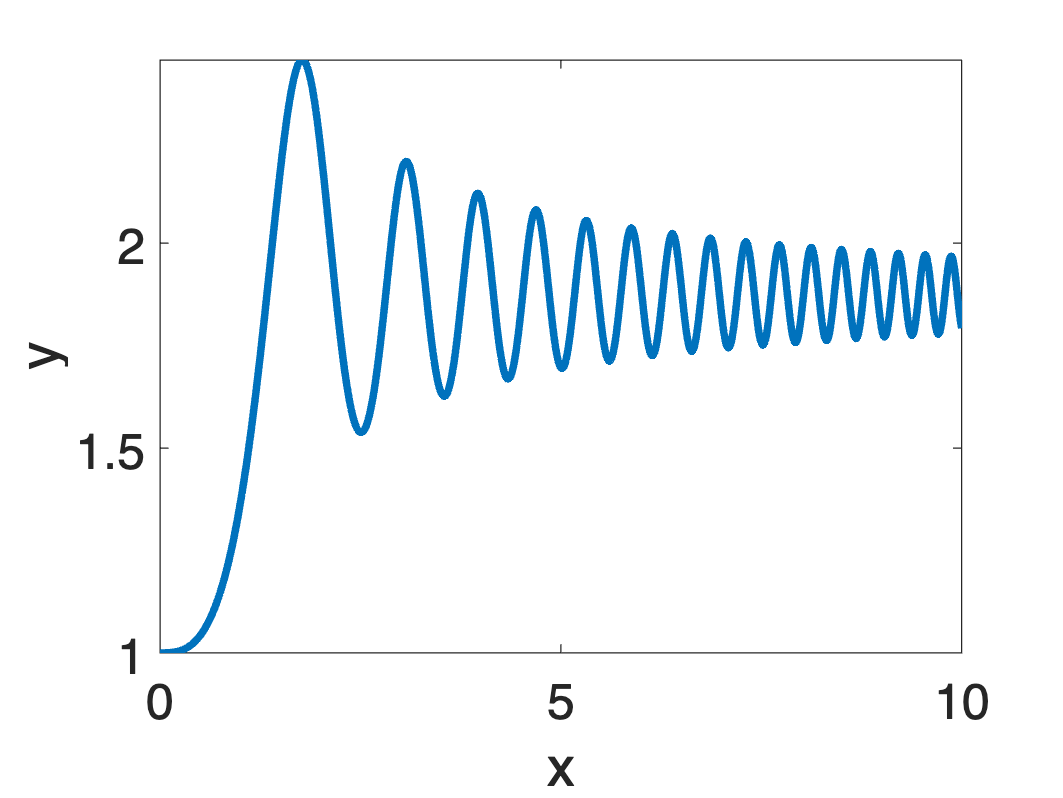

fplot(ySol,[0 10],'linewidth',3);hold on
xlabel('x','FontSize',20)
ylabel('y','FontSize',20)
set(gca,'fontsize',20)

### ODE Boundary Value Problems

Another type of ODE problem is a "Boundary Value Problem" (technically an IVP is a type of BVP with only one BC) where we have multiple conditions on the solution (boundary conditions) where the function we are solving for has known values at two locations (if problem is in one dimension). BVPs sometimes do not have solutions or do not have unique solutions (as opposed to IVPs which are more likely to have unique solutions). We will use a particularly well behaved BVP as an example: $y\prime^{\prime } +4y=0$ with boundary conditions: $y\left(0\right)=-2$ and $y\left(\frac{\pi }{4}\right)=10$.

#### Numerical solution to BVPs

First lets define a function for this ODE (split into two first-order ODEs)

odebvp = @(x,y) [y(2);-4*y(1)]

odebvp = function_handle with value:
    @(x,y)[y(2);-4*y(1)]


And also a function defining the boundary conditions (where the output is zero when the BCs are satisfied)

bcfcn = @(ya,yb) [ya(1)+2;yb(1)-0]

bcfcn = function_handle with value:
    @(ya,yb)[ya(1)+2;yb(1)-0]


And a function for the initial guess (this just has to be somewhere in the vicinity of any potential answer)

guess = @(x) [sin(x);cos(x)]

guess = function_handle with value:
    @(x)[sin(x);cos(x)]


Then we can define an initial solution using the bvpinit function

xmesh = linspace(0,pi/4,20);
solinit = bvpinit(xmesh, guess);

Then finally, we can solve the BVP numerically using one of several BVP solvers available in MATLAB. We will use bvp4c, the most widely used, that implements an accurate bvp solution method.

sol = bvp4c(odebvp, bcfcn, solinit)

sol = struct with fields:
    solver: 'bvp4c'
         x: [0 0.0413 0.0827 0.1240 0.1653 0.2067 0.2480 0.2894 0.3307 0.3720 0.4134 0.4547 0.4960 0.5374 0.5787 0.6201 0.6614 0.7027 0.7441 0.7854]
         y: [2×20 double]
        yp: [2×20 double]
     stats: [1×1 struct]


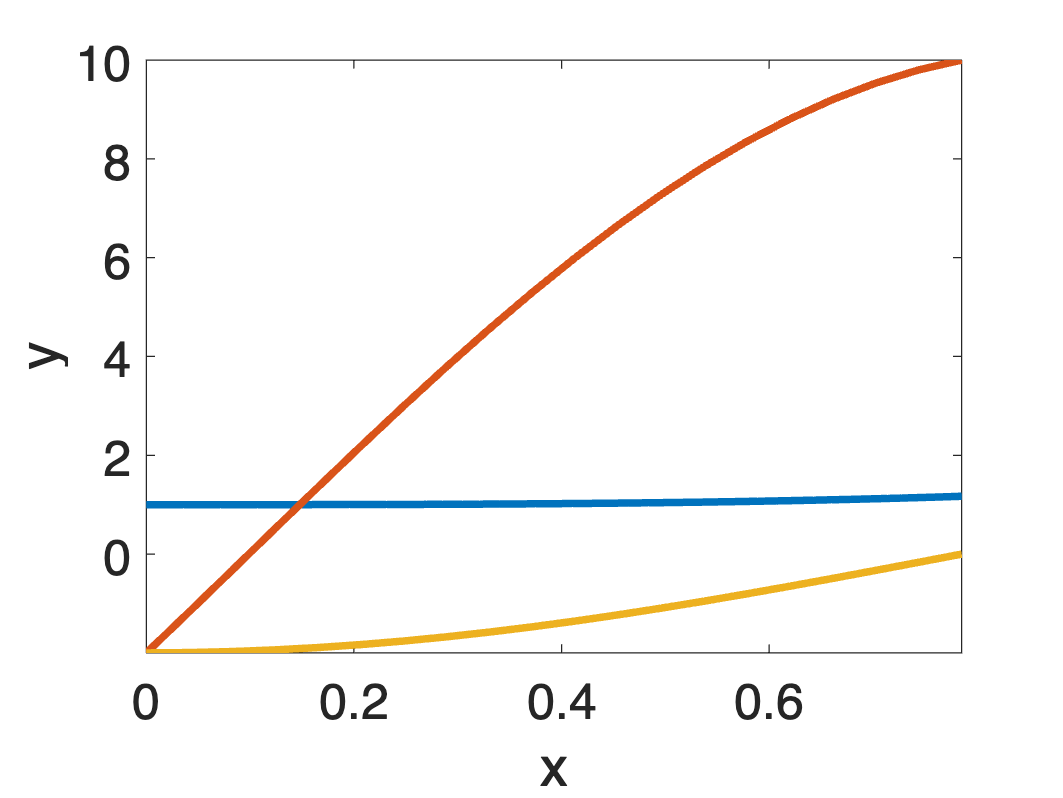

plot(sol.x, sol.y(1,:),'linewidth',3);hold on
xlabel('x','FontSize',20)
ylabel('y','FontSize',20)
xlim([0 pi/4])
set(gca,'fontsize',20)

#### Symbolic/Analytic solutions to BVPs

Nicely, the IVP ode solver in MATLAB's Symbolic math toolbox is the same that one would use for BVPs, using nearly identical syntax, but just providing two BCs. So we define the function and ODE

syms y(t)
ode = diff(y,t,2) == -4*y

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=-4\,y\left(t\right)$$

Then the two BCs are provided as a vector

bc1 = y(0) == -2;
bc2 = y(pi/4) == 10;
bcs = [bc1 bc2]

$$bcs = \left(\begin{array}{cc} y\left(0\right)=-2 & y\left(\frac{\pi }{4}\right)=10 \end{array}\right)$$

...and solve

ysol(t) = dsolve(ode,bcs)

$$ysol(t) = 10\,\sin\left(2\,t\right)-2\,\cos\left(2\,t\right)$$


hold off

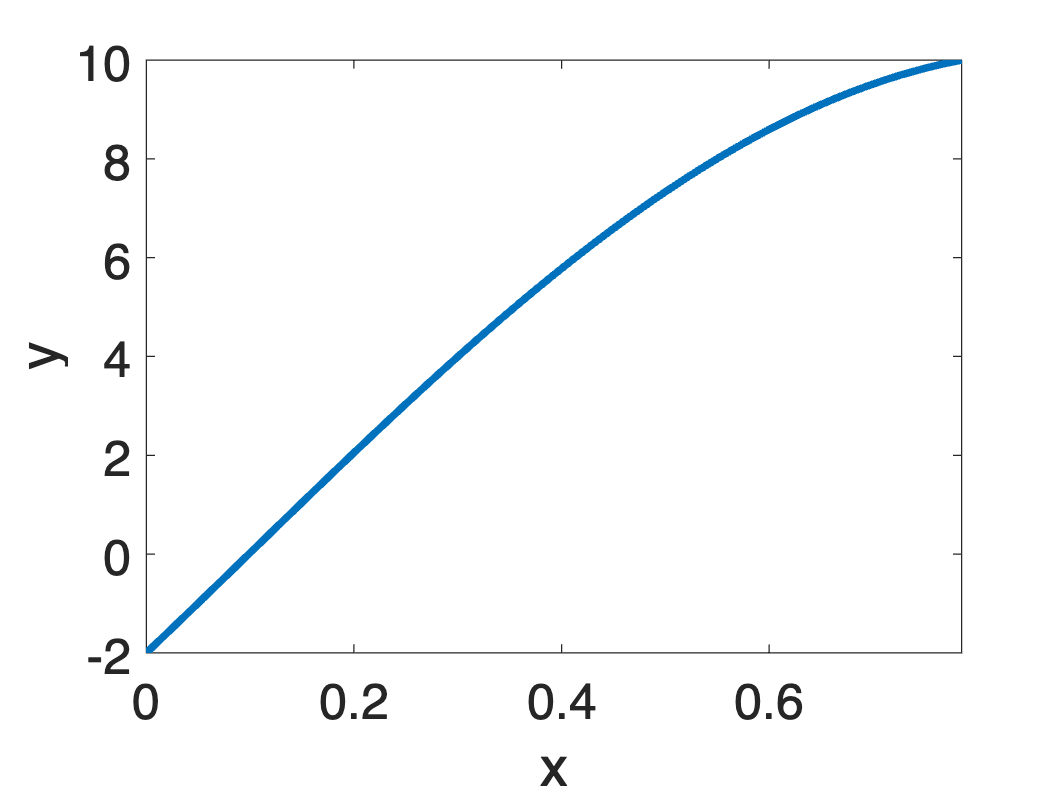

fplot(ysol,[0 pi/4],'linewidth',3);hold on
xlabel('x','FontSize',20)
ylabel('y','FontSize',20)
set(gca,'fontsize',20)